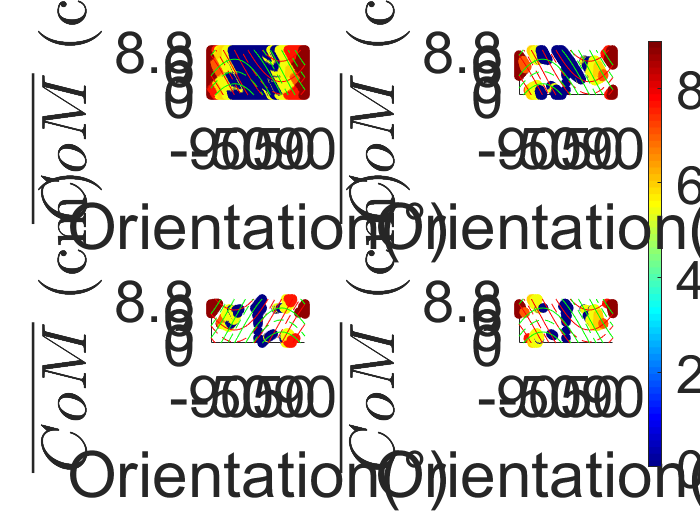

%% Initial parameters setup
StepNum = 20; %total number of steps being simulated
HalfBodyLength = 7.8; %cm
HalfBodyWidth = 7.75; %cm
HalfBodyDiag = sqrt(HalfBodyLength^2+HalfBodyWidth^2);
beta_rad = atan(HalfBodyWidth/HalfBodyLength); % robot aspect ratio angle (radians)
StepLengthlist =9.2; %cm for bounding gait %1, 13.5cm for bounding gait  %2, 13.2cm for trotting gait  %3, 9.2cm for pacing gait

LogNum = 21;
LogDiameter = 4.8; %cm
D = LogDiameter;
LogSpacing = 4.0; %cm
P = LogSpacing;
C = HalfBodyDiag;
X_k_ini = 2*(P+D); %cm

resolution_angle = 1;% decide loop size for robot initial angle
resolution_pos = 0.1;% decide loop size for robot initial position

SIZE = round((LogDiameter + LogSpacing)/resolution_pos+1); % define the size of data matrix
Theta_k_minus = zeros(181/resolution_angle+1,SIZE,StepNum); % Matrix for collecting robot orientation before each slides
Theta_k_plus = zeros(181/resolution_angle+1,SIZE,StepNum);  % Matrix for collecting robot orientation after each slides
X_k_minus = zeros(181/resolution_angle+1,SIZE,StepNum);     % Matrix for collecting robot position of CoM before each slides
X_k_plus = zeros(181/resolution_angle+1,SIZE,StepNum);      % Matrix for collecting robot position of CoM after each slides
X_lateral = zeros(181/resolution_angle+1,SIZE,StepNum);     % Matrix for collecting robot lateral position of CoM after each slides
S_L = zeros(181/resolution_angle+1,SIZE,StepNum);           % Matrix for collecting robot left leg slide distance
S_R = zeros(181/resolution_angle+1,SIZE,StepNum);           % Matrix for collecting robot right leg slide distance

State_Space = zeros(360/resolution_angle + 1, (P + D)/resolution_pos + 1, StepNum);% Initialize State Space
color_space = zeros(180/resolution_angle + 1, (P + D)/resolution_pos + 1, 1);% Initialize Color Space
MarkerEdgeColors =jet(91);

%% Main Loop
Ang = 0;gait = 3; % 1 is bounding, 2 is trotting, and 3 is pacing
for Initial_Angle = -90 : 90/resolution_angle
    Pos = 0;
    Ang = Ang + 1;
    for X_k = 0 : 0.1 : (P + D)
        Pos = Pos + 1;
        X_k_minus(Ang,Pos,1) = X_k;
        X_lateral(Ang,Pos,1) = 0;
        Theta_k_minus(Ang,Pos,1) = Initial_Angle/180*pi;
        if(gait==1)
            for i=1:StepNum %Main loop for bounding gait start
                if (mod(i,2)==1)
                    [X_k_plus(Ang,Pos,i),Theta_k_plus(Ang,Pos,i),S_L(Ang,Pos,i),S_R(Ang,Pos,i)]=Mode1_B(X_k_minus(Ang,Pos,i), Theta_k_minus(Ang,Pos,i), LogSpacing, LogDiameter, HalfBodyWidth, HalfBodyLength, beta_rad, HalfBodyDiag);
                    [X_k_minus(Ang,Pos,i+1),Theta_k_minus(Ang,Pos,i+1),X_lateral(Ang,Pos,i+1)] = Mode2_B(X_k_plus(Ang,Pos,i), Theta_k_plus(Ang,Pos,i),X_lateral(Ang,Pos,i), StepLengthlist);
                else
                    [X_k_plus(Ang,Pos,i),Theta_k_plus(Ang,Pos,i),S_L(Ang,Pos,i),S_R(Ang,Pos,i)]=Mode3_B(X_k_minus(Ang,Pos,i), Theta_k_minus(Ang,Pos,i), LogSpacing, LogDiameter, HalfBodyWidth, HalfBodyLength, beta_rad, HalfBodyDiag);
                    [X_k_minus(Ang,Pos,i+1),Theta_k_minus(Ang,Pos,i+1),X_lateral(Ang,Pos,i+1)] = Mode4_B(X_k_plus(Ang,Pos,i), Theta_k_plus(Ang,Pos,i),X_lateral(Ang,Pos,i), StepLengthlist);
                end
            end %Main loop for bounding gait end
        elseif(gait==2)
            for i=1:StepNum %Main loop for trotting gait start
                if (mod(i,2)==1)
                    [X_k_plus(Ang,Pos,i),Theta_k_plus(Ang,Pos,i),S_L(Ang,Pos,i),S_R(Ang,Pos,i)]=Mode1_T(X_k_minus(Ang,Pos,i), Theta_k_minus(Ang,Pos,i), LogSpacing, LogDiameter, HalfBodyWidth, HalfBodyLength, beta_rad, HalfBodyDiag);
                    [X_k_minus(Ang,Pos,i+1),Theta_k_minus(Ang,Pos,i+1),X_lateral(Ang,Pos,i+1)] = Mode2_T(X_k_plus(Ang,Pos,i), Theta_k_plus(Ang,Pos,i),X_lateral(Ang,Pos,i), StepLengthlist);
                else
                    [X_k_plus(Ang,Pos,i),Theta_k_plus(Ang,Pos,i),S_L(Ang,Pos,i),S_R(Ang,Pos,i)]=Mode3_T(X_k_minus(Ang,Pos,i), Theta_k_minus(Ang,Pos,i), LogSpacing, LogDiameter, HalfBodyWidth, HalfBodyLength, beta_rad, HalfBodyDiag);
                    [X_k_minus(Ang,Pos,i+1),Theta_k_minus(Ang,Pos,i+1),X_lateral(Ang,Pos,i+1)] = Mode4_T(X_k_plus(Ang,Pos,i), Theta_k_plus(Ang,Pos,i),X_lateral(Ang,Pos,i), StepLengthlist);
                end
            end %Main loop for trotting gait end
        elseif(gait==3)
            for i=1:StepNum %Main loop for pacing gait start
                if (mod(i,2)==1)
                    [X_k_plus(Ang,Pos,i),Theta_k_plus(Ang,Pos,i),S_L(Ang,Pos,i),S_R(Ang,Pos,i)]=Mode1_P(X_k_minus(Ang,Pos,i), Theta_k_minus(Ang,Pos,i), LogSpacing, LogDiameter, HalfBodyWidth, HalfBodyLength, beta_rad, HalfBodyDiag);
                    [X_k_minus(Ang,Pos,i+1),Theta_k_minus(Ang,Pos,i+1),X_lateral(Ang,Pos,i+1)] = Mode2_P(X_k_plus(Ang,Pos,i), Theta_k_plus(Ang,Pos,i),X_lateral(Ang,Pos,i), StepLengthlist);
                else
                    [X_k_plus(Ang,Pos,i),Theta_k_plus(Ang,Pos,i),S_L(Ang,Pos,i),S_R(Ang,Pos,i)]=Mode3_P(X_k_minus(Ang,Pos,i), Theta_k_minus(Ang,Pos,i), LogSpacing, LogDiameter, HalfBodyWidth, HalfBodyLength, beta_rad, HalfBodyDiag);
                    [X_k_minus(Ang,Pos,i+1),Theta_k_minus(Ang,Pos,i+1),X_lateral(Ang,Pos,i+1)] = Mode4_P(X_k_plus(Ang,Pos,i), Theta_k_plus(Ang,Pos,i),X_lateral(Ang,Pos,i), StepLengthlist);
                end
            end %Main loop for pacing gait end
        end
    end
end

for Ang = 1: 180/resolution_angle + 1
    for Pos = 1 : (P + D)/resolution_pos + 1
        for Step = 1: StepNum
            if(round(Theta_k_plus(Ang,Pos,Step)/pi*180) + 91 > 0)
                State_Space(round(Theta_k_plus(Ang,Pos,Step)/pi*180) + 91 , round(mod(real(X_k_plus(Ang,Pos,Step)*10),(P+D)*10) + 1), Step) = State_Space(round(Theta_k_plus(Ang,Pos,Step)/pi*180) + 91 , round(mod(real(X_k_plus(Ang,Pos,Step)*10),(P+D)*10) + 1), Step) + 1;
            end
        end
    end
end

for Ang = 1: 180/resolution_angle + 1
    for Pos = 1 : (P + D)/resolution_pos + 1
        if(abs(round(Theta_k_plus(Ang,Pos,20)/pi*180)) <= 90)
            color_space(Ang, Pos, 1) = abs(round(Theta_k_plus(Ang,Pos,20)/pi*180));
        else
            color_space(Ang, Pos, 1) = 90 ;
        end
    end
end

ShowNum = 4;  %total number of steps being simulated
clf;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Boudning gait
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if(gait == 1)
    % subplot(2,3,6);hold on;
    % if(ShowNum>0)
    %     for Ang = 1 : 180/resolution_angle + 1
    %         for Pos = 1 : (P + D)/resolution_pos + 1
    %             xlim([-90 90]);
    %             ylim([0 9.0]);
    %             if(State_Space(Ang , Pos, ShowNum)>0)
    %                 plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20);
    %             end
    %         end
    %     end
    % else
    %     for Ang = 91 : 180/resolution_angle + 1
    %         for Pos = 1 : (P + D)/resolution_pos + 1
    %             xlim([-90 90]);
    %             ylim([0 9.0]);
    %             plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20);
    %         end
    %     end
    % end
    % xlabel("Orientation(°)");
    % ylabel("CoM (cm)");
    % t=-90:90;
    % plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    % set(gca,'Fontsize',35);
    %
    % subplot(2,3,5); hold on;
    % if(ShowNum-1>0)
    %     for Ang = 1 : 180/resolution_angle + 1
    %         for Pos = 1 : (P + D)/resolution_pos + 1
    %             xlim([-90 90]);
    %             ylim([0 9.0]);
    %             if(State_Space(Ang , Pos, ShowNum-1)>0)
    %                 plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20);
    %             end
    %         end
    %     end
    % else
    %     for Ang = 91 : 180/resolution_angle + 1
    %         for Pos = 1 : (P + D)/resolution_pos + 1
    %             xlim([-90 90]);
    %             ylim([0 9.0]);
    %             plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20);
    %         end
    %     end
    % end
    % xlabel("Orientation(°)");
    % ylabel("CoM (cm)");
    % t=-90:90;
    % plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    % set(gca,'Fontsize',35);
    
    subplot(2,2,4); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-1)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    set(gca,'Fontsize',35);
    
    subplot(2,2,3); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-2)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    % plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, D+P+C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D+C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D/2+C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 0+C*cos(t/180*pi+beta_rad), 'r');
    plot(t, -P+C*cos(t/180*pi+beta_rad), 'r');
    plot(t, -D/2-P+C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, -D-P+C*cos(t/180*pi+beta_rad), 'r');
    plot(t, -D-2*P+C*cos(t/180*pi+beta_rad), 'r');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, -2*D-2*P+C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, D+P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D/2+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 0+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D/2-P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -D-P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -2*D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    set(gca,'Fontsize',35);
    
    % plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    
    subplot(2,2,2); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-3)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    set(gca,'Fontsize',35);
    
    subplot(2,2,1); hold on;
    if(ShowNum-4>0)
        for Ang = 1 : 180/resolution_angle + 1
            for Pos = 1 : (P + D)/resolution_pos + 1
                xlim([-90 90]);
                ylim([0 9.0]);
                if(State_Space(Ang , Pos, ShowNum-4)>0)
                    plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
                end
            end
        end
    else
        for Ang = 1 : 180/resolution_angle + 1
            for Pos = 1 : (P + D)/resolution_pos + 1
                xlim([-90 90]);
                ylim([0 9.0]);
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:900;
    
    if(ShowNum-4>0)
        % plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, D+P+C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D+C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D/2+C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, 0+C*cos(t/180*pi+beta_rad), 'r');
        plot(t, -P+C*cos(t/180*pi+beta_rad), 'r');
        plot(t, -D/2-P+C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, -D-P+C*cos(t/180*pi+beta_rad), 'r');
        plot(t, -D-2*P+C*cos(t/180*pi+beta_rad), 'r');
        plot(t, -3/2*D-2*P+C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, -2*D-2*P+C*cos(t/180*pi+beta_rad), 'r');
        % plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, D+P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D/2+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, 0+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -D/2-P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, -D-P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -D-2*P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -3/2*D-2*P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, -2*D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    else
        plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
        plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
        plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
        plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    end
    
    set(gca,'Fontsize',35);
    hp4 = get(subplot(2,2,4),'Position');
    colorbar('Position', [hp4(1)+hp4(3)+0.02  hp4(2)  0.02  hp4(2)+hp4(3)*2.1]);colormap('jet');caxis([0,90]);
end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Trotting gait
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if(gait == 2)
    subplot(2,2,4); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-1)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    
    plot(t, -P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 3/2*D+P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, D+P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D/2+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 0+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D/2-P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -D-P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -2*D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    
    set(gca,'Fontsize',35);
    
    subplot(2,2,3); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-2)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    
    plot(t, -P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 2*D+P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, D+P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, D+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, D/2+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, 0+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -D/2-P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, -D-P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, -2*D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    
    set(gca,'Fontsize',35);
    
    % plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    
    subplot(2,2,2); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-3)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    
    plot(t, -P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 3/2*D+P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, D+P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D/2+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 0+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D/2-P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -D-P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -2*D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    
    set(gca,'Fontsize',35);
    
    subplot(2,2,1); hold on;
    if(ShowNum-4>0)
        for Ang = 1 : 180/resolution_angle + 1
            for Pos = 1 : (P + D)/resolution_pos + 1
                xlim([-90 90]);
                ylim([0 9.0]);
                if(State_Space(Ang , Pos, ShowNum-4)>0)
                    plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
                end
            end
        end
    else
        for Ang = 1 : 180/resolution_angle + 1
            for Pos = 1 : (P + D)/resolution_pos + 1
                xlim([-90 90]);
                ylim([0 9.0]);
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:900;
    if(ShowNum-4>0)
        plot(t, -P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 2*D+P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, D+P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, D+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, D/2+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, 0+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -D/2-P+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, -D-P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -D-2*P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -3/2*D-2*P+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, -2*D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    else
        plot(t, -P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 0-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, D/2-C*cos(t/180*pi-beta_rad), 'r--');
        plot(t, D-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, D+P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'r--');
        plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'r--');
        plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 2*D+P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, 3/2*D+P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, D+P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D/2+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, 0+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -D/2-P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, -D-P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -D-2*P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -3/2*D-2*P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, -2*D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    end
    
    set(gca,'Fontsize',35);
    hp4 = get(subplot(2,2,4),'Position');
    colorbar('Position', [hp4(1)+hp4(3)+0.02  hp4(2)  0.02  hp4(2)+hp4(3)*2.1]);colormap('jet');caxis([0,90]);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Pacing gait
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if(gait == 3)
    subplot(2,2,4); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-1)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    
    plot(t, -P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, D+P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, D+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, D/2+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, 0+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -D/2-P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, -D-P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, -2*D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    
    set(gca,'Fontsize',35);
    
    subplot(2,2,3); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-2)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    
    plot(t, -P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    plot(t, 2*D+P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, 3/2*D+P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, D+P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, D/2+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, 0+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D/2-P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -D-P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi-beta_rad), 'g--');
    plot(t, -2*D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    
    set(gca,'Fontsize',35);
    
    % plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
    % plot(t, 0-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D/2-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, D-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    % plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'g--');
    % plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'g');
    
    subplot(2,2,2); hold on;
    for Ang = 1 : 180/resolution_angle + 1
        for Pos = 1 : (P + D)/resolution_pos + 1
            xlim([-90 90]);
            ylim([0 9.0]);
            if(State_Space(Ang , Pos, ShowNum-3)>0)
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:90;
    
    plot(t, -P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 0-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D/2-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, D-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'r--');
    plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
    plot(t, 2*D+P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, D+P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, D+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, D/2+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, 0+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -D/2-P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, -D-P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    plot(t, -3/2*D-2*P+C*cos(t/180*pi+beta_rad), 'g--');
    plot(t, -2*D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    
    set(gca,'Fontsize',35);
    
    subplot(2,2,1); hold on;
    if(ShowNum-4>0)
        for Ang = 1 : 180/resolution_angle + 1
            for Pos = 1 : (P + D)/resolution_pos + 1
                xlim([-90 90]);
                ylim([0 9.0]);
                if(State_Space(Ang , Pos, ShowNum-4)>0)
                    plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
                end
            end
        end
    else
        for Ang = 1 : 180/resolution_angle + 1
            for Pos = 1 : (P + D)/resolution_pos + 1
                xlim([-90 90]);
                ylim([0 9.0]);
                plot(Ang-91, (Pos-1)/10.0, '.','MarkerSize', 20,'color',MarkerEdgeColors(color_space(Ang, Pos, 1)+1,:),'linewidth',8);
            end
        end
    end
    xlabel("Orientation(°)");xticks([-90 -50 0 50 90]);
    ylabel('$\overline{CoM}$ (cm)','interpreter','latex');yticks([0 3 6 8.8]);
    ylim([0 P+D]);
    t=-90:900;
    if(ShowNum-4>0)
        plot(t, -P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 0-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D/2-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, D-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, D+P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 3/2*D+P-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, 2*D+P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 2*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 5/2*D+2*P-C*cos(t/180*pi+beta_rad), 'r--');
        plot(t, 3*D+2*P-C*cos(t/180*pi+beta_rad), 'r');
        plot(t, 2*D+P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, 3/2*D+P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, D+P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, D/2+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, 0+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -D/2-P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, -D-P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -D-2*P+C*cos(t/180*pi-beta_rad), 'g');
        plot(t, -3/2*D-2*P+C*cos(t/180*pi-beta_rad), 'g--');
        plot(t, -2*D-2*P+C*cos(t/180*pi-beta_rad), 'g');
    else
        plot(t, -P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 0-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, D/2-C*cos(t/180*pi-beta_rad), 'r--');
        plot(t, D-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, D+P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 3/2*D+P-C*cos(t/180*pi-beta_rad), 'r--');
        plot(t, 2*D+P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 2*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 5/2*D+2*P-C*cos(t/180*pi-beta_rad), 'r--');
        plot(t, 3*D+2*P-C*cos(t/180*pi-beta_rad), 'r');
        plot(t, 2*D+P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, 3/2*D+P+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, D+P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, D+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, D/2+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, 0+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -D/2-P+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, -D-P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -D-2*P+C*cos(t/180*pi+beta_rad), 'g');
        plot(t, -3/2*D-2*P+C*cos(t/180*pi+beta_rad), 'g--');
        plot(t, -2*D-2*P+C*cos(t/180*pi+beta_rad), 'g');
    end
    
    set(gca,'Fontsize',35);
    hp4 = get(subplot(2,2,4),'Position');
    colorbar('Position', [hp4(1)+hp4(3)+0.02  hp4(2)  0.02  hp4(2)+hp4(3)*2.1]);colormap('jet');caxis([0,90]);
end